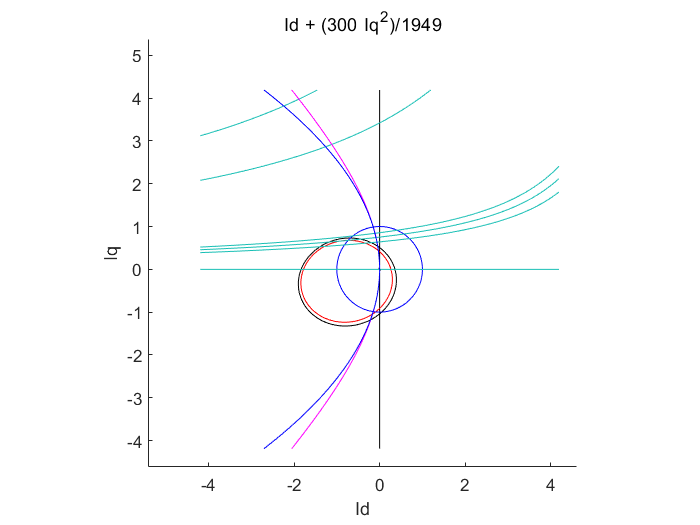

clear;
%close all;

%Parameter define
DC_max = 300*0.8;
Ld = 0.22;
Lq = 0.25;
Rs = 49.5;
Pasi = 0.1949;
Pole_pair = 4;
Omega_m = 545; %% Hz
I_max = 1;%17.5;
Id_max = -10; %-0.35*25;
Te = 5;

%Calculate
syms Id Iq; 
Omega_e = 502;
% figure set
figure;
axis equal;
%ezplot(Iq*(Id-Id_max),[-30,30,-30,30]);

hold on;
h = ezplot(Id*Iq,[-4.19,4.19,-4.19,4.19]);
set(h,'color','k');

hold on;
% plot voltage oval
h = ezplot((-Omega_e*Lq*Iq+Id*Rs).^2+(Omega_e*Ld*Id+Omega_e*Pasi+Iq*Rs).^2 - (DC_max/sqrt(3)).^2,[-4.19,4.19,-4.19,4.19]);
set(h,'color','k');

hold on;
Omega_e = 545;
h = ezplot((-Omega_e*Lq*Iq+Id*Rs).^2+(Omega_e*Ld*Id+Omega_e*Pasi+Iq*Rs).^2 - (DC_max/sqrt(3)).^2,[-4.19,4.19,-4.19,4.19]);
set(h,'color','r');

hold on;
Omega_e = 545;
h = ezplot((-Omega_e*Lq*Iq+Id*Rs).^2+(Omega_e*Ld*Id+Omega_e*Pasi+Iq*Rs).^2 - (DC_max/sqrt(3)).^2,[-4.19,4.19,-4.19,4.19]);
set(h,'color','r');

% plot current circle
hold on ;
h = ezplot(Id.^2+Iq.^2 - I_max.^2,[-4.16,4.16,-4.16,4.16]);
set(h,'color','b');



% plot Te limit
Te = 0;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-4.19,4.19,-4.19,4.19]);

Te = 1;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-4.19,4.19,-4.19,4.19]);

Te = 0.75;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-4.19,4.19,-4.19,4.19]);

Te = 0.88;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-4.19,4.19,-4.19,4.19]);

Te = 4;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-4.19,4.19,-4.19,4.19]);


Te = 6;
hold on;
ezplot(((Pasi*Iq+(Ld-Lq)*Id*Iq)*Pole_pair*1.5)-Te,[-4.19,4.19,-4.19,4.19]);

%plot MTPA
hold on;
h = ezplot(2*(Lq-Ld)*Id+sqrt(Pasi.^2+(4*(Lq-Ld).^2)*Iq.^2)-Pasi,[-4.19,4.19,-4.19,4.19]);
set(h,'color','m');

hold on;
h = ezplot(Id-Iq*Iq*(Ld-Lq)/Pasi,[-4.19,4.19,-4.19,4.19]);
set(h,'color','b');

% %plot Vq
% hold on;
% h = ezplot(100-Iq*Rs-1885*Ld*Id-1885*Pasi,[-20,20,-20,20]);
% set(h,'color','m');
% 
% hold on;
% h = ezplot(130-Iq*Rs-1885*Ld*Id-1885*Pasi,[-20,20,-20,20]);
% set(h,'color','k');
% 
% hold on;
% h = ezplot(140-Iq*Rs-1885*Ld*Id-1885*Pasi,[-20,20,-20,20]);
% set(h,'color','b');
% 
% %plot Vd
% hold on;
% h = ezplot(-100-Id*Rs+1885*Ld*Iq,[-20,20,-20,20]);
% set(h,'color','m');
% 
% hold on;
% h = ezplot(-130-Id*Rs+1885*Ld*Iq,[-20,20,-20,20]);
% set(h,'color','k');
% 
% hold on;
% h = ezplot(-140-Id*Rs+1885*Ld*Iq,[-20,20,-20,20]);
% set(h,'color','b');



xlim([-5 5])
ylim([-5 5])